# continuousCultureTheroy

Shuai Yang

2023/3/24

考虑整个生长周期，对数期稳定期，细菌的生长率mu采用Monod equation 表示


$$\mu = \mu_{max} \  \frac{S}{K_S+S}$$


细菌生长率$\mu$ 单位hr-1，$\mu_{max}$最大生长率，假设细菌最快分裂时间为0.5hr，则$\mu_{max} = \frac{\mathrm{ln}2}{0.5} = 1.38\ \mathrm{h^{-1}}$

$\frac{\mathrm{d}X}{\mathrm{d}t} = \mu X$；细菌数目（或mass 或OD）的变化

X = 0.1;             % 细菌的初始量 biomass 或者 cell number
mu_max = log(2)/0.8;    % 最大生长率 单位h-1
S = 500;            %基底营养物质浓度 单位mg/L
K_S = 20;            %特征饱和浓度 单位mg/L
mu = mu_max*S/(K_S+S);
dX = mu*X;  % 细菌初始量的变化

基底营养物质的利用也可以用Monod equation 方程进行描述

$\frac{\mathrm{d}S}{\mathrm{d}t} =-\frac{1}{Y}\  \frac{\mathrm{d}X}{\mathrm{d}t}$；细菌数目（或mass 或OD）的变化

Y 可以理解为消耗单位质量的基底营养物质所能生产的细菌的量biomass

Y = 0.5;
dS = -1/Y*dX; % 基质营养物质的消耗

模拟

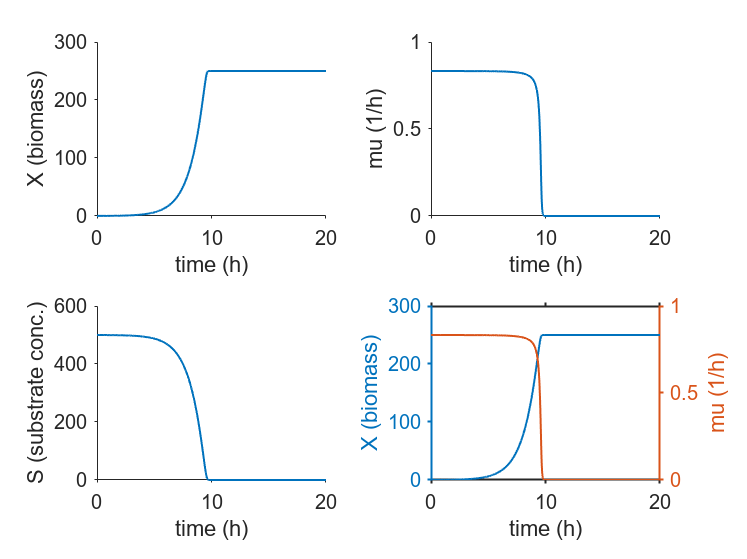

delt_t = 0.01;  % 时间间隔 h；0.02 h = 1.2 min
N = 2000;   %时间点的数目

X_array = nan(N,1);
S_array = nan(N,1);

dX_array = nan(N-1,1);
dS_array = nan(N-1,1);
mu_array = nan(N-1,1);

X_array(1) = X;
S_array(1) = S;

for k = 2:N+1
    X = X_array(k-1);
    S = S_array(k-1);
    mu = mu_max*S/(K_S+S);
    dX = mu*X;
    dS = -1/Y*dX;
    X_array(k) = X + dX * delt_t;
    S_array(k) = S + dS * delt_t;
    dX_array(k-1) = dX;
    dS_array(k-1) = dS;
    mu_array(k-1) = mu;

end

figure,
ax1 = nexttile;
plot((0:N)*delt_t, X_array,'LineWidth',1)
set(ax1,'Tickdir','out','Box','off','FontSize',10);
xlabel(ax1,'time (h)')
ylabel(ax1,'X (biomass)')

ax1 = nexttile;
plot((1:N)*delt_t, mu_array,'LineWidth',1)
set(ax1,'Tickdir','out','Box','off','FontSize',10);
xlabel(ax1,'time (h)')
ylabel(ax1,'mu (1/h)')

ax1 = nexttile;
plot((0:N)*delt_t, S_array,'LineWidth',1)
set(ax1,'Tickdir','out','Box','off','FontSize',10);
xlabel(ax1,'time (h)')
ylabel(ax1,'S (substrate conc.)')

ax1 = nexttile;
yyaxis left
plot((0:N)*delt_t, X_array,'LineWidth',1)
xlabel(ax1,'time (h)')
ylabel(ax1,'X (biomass)')
yyaxis right
plot((1:N)*delt_t, mu_array,'LineWidth',1)
set(ax1,'Tickdir','out','FontSize',10,'LineWidth',1);
ylabel(ax1,'mu (1/h)')

考虑持续稀释 引入持续稀释率D

$\frac{\mathrm{d}X}{\mathrm{d}t} = \mu X- DX$；细菌数目（或mass 或OD）的变化

D 需要小于$\mu_{max}$，要不然细菌的数目会一致减少

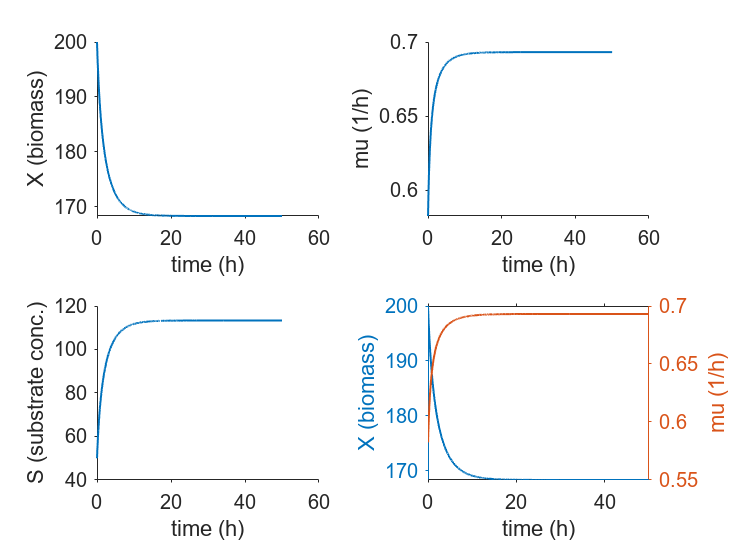

X0 = 200;             % 细菌的初始量 biomass 或者 cell number
mu_max = log(2)/0.85;    % 最大生长率 单位h-1
S0 = 50;            %基底营养物质浓度 单位mg/L
K_S = 20;            %特征饱和浓度 单位mg/L
Y = 0.5;
D = log(2)/1;

delt_t = 0.01;  % 时间间隔 h；0.02 h 0= 1.2 min
N = 5000;   %时间点的数目

X_array = nan(N,1);
S_array = nan(N,1);

dX_array = nan(N-1,1);
dS_array = nan(N-1,1);
dX_out = nan(N-1,1);
mu_array = nan(N-1,1);

X_array(1) = X0;
S_array(1) = S0;

for k = 2:N+1
    X = X_array(k-1);
    S = S_array(k-1);
    mu = mu_max*S/(K_S+S);
    dX = mu*X-D*X;
    dS = -1/Y*dX;
    X_array(k) = X + dX * delt_t;
    S_array(k) = S + dS * delt_t;
    dX_array(k-1) = dX;
    dS_array(k-1) = dS;
    dX_out(k-1) = D*X;
    mu_array(k-1) = mu;

end

figure,
ax1 = nexttile;
plot((0:N)*delt_t, X_array,'LineWidth',1)
set(ax1,'Tickdir','out','Box','off','FontSize',10);
xlabel(ax1,'time (h)')
ylabel(ax1,'X (biomass)')

ax1 = nexttile;
plot((1:N)*delt_t, mu_array,'LineWidth',1)
set(ax1,'Tickdir','out','Box','off','FontSize',10);
xlabel(ax1,'time (h)')
ylabel(ax1,'mu (1/h)')

ax1 = nexttile;
plot((0:N)*delt_t, S_array,'LineWidth',1)
set(ax1,'Tickdir','out','Box','off','FontSize',10);
xlabel(ax1,'time (h)')
ylabel(ax1,'S (substrate conc.)')

ax1 = nexttile;
yyaxis left
plot((0:N)*delt_t, X_array,'LineWidth',1)
xlabel(ax1,'time (h)')
ylabel(ax1,'X (biomass)')
yyaxis right
plot((1:N)*delt_t, mu_array,'LineWidth',1)
set(ax1,'Tickdir','out','FontSize',10);
ylabel(ax1,'mu (1/h)')
xlim(ax1,[0,N]*delt_t)

考虑间断性稀释 与自动化实验过程相符 每1h稀释1次 取出1/2 加入1/2新鲜培养基

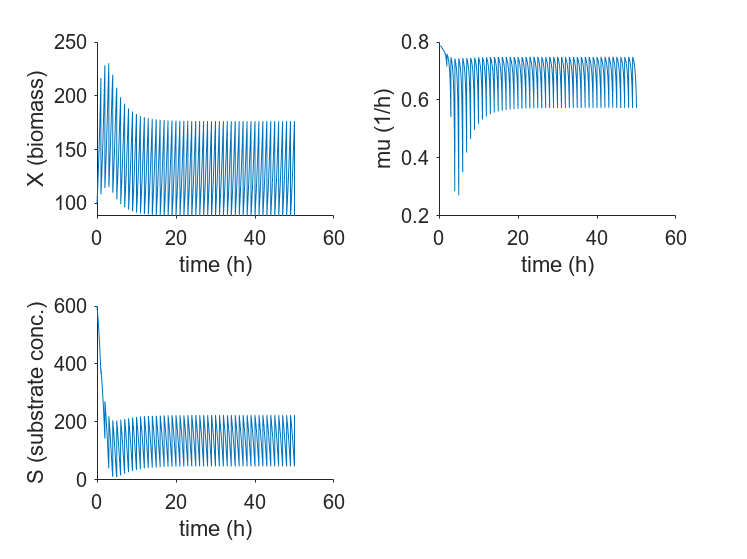

X0 = 100;             % 细菌的初始量 biomass 或者 cell number 自动化实验较大
mu_max = log(2)/0.85;    % 最大生长率 单位h-1
S0 = 600;            %基底营养物质浓度 单位mg/L
K_S = 20;            %特征饱和浓度 单位mg/L
Y = 0.5;

delt_t = 0.01;  % 时间间隔 h；0.02 h = 1.2 min
N = 5000;   %时间点的数目

X_array = nan(N,1);
S_array = nan(N,1);

dX_array = nan(N-1,1);
dS_array = nan(N-1,1);
dX_out = nan(N-1,1);
mu_array = nan(N-1,1);

X_array(1) = X0;
S_array(1) = S0;

for k = 2:N+1
    X = X_array(k-1);
    S = S_array(k-1);
    mu = mu_max*S/(K_S+S);
    if  mod(k,100) == 1 % 每1h稀释1次
        X_array(k) = X*0.5;
%         S_array(k) = S +200;
        S_array(k) = S/2 + 200;
        dX_out(k-1) = X*0.5;

    else
        dX = mu*X;
        dS = -1/Y*dX;
        X_array(k) = X + dX * delt_t;
        S_array(k) = S + dS * delt_t;
        dX_array(k-1) = dX;
        dS_array(k-1) = dS;

    end
    mu_array(k-1) = mu;


end

figure,
ax1 = nexttile;
plot((0:N)*delt_t, X_array)
set(ax1,'Tickdir','out','Box','off','FontSize',10);
xlabel(ax1,'time (h)')
ylabel(ax1,'X (biomass)')

ax1 = nexttile;
plot((1:N)*delt_t, mu_array)
set(ax1,'Tickdir','out','Box','off','FontSize',10);
xlabel(ax1,'time (h)')
ylabel(ax1,'mu (1/h)')

ax1 = nexttile;
plot((0:N)*delt_t, S_array)
set(ax1,'Tickdir','out','Box','off','FontSize',10);
xlabel(ax1,'time (h)')
ylabel(ax1,'S (substrate conc.)')

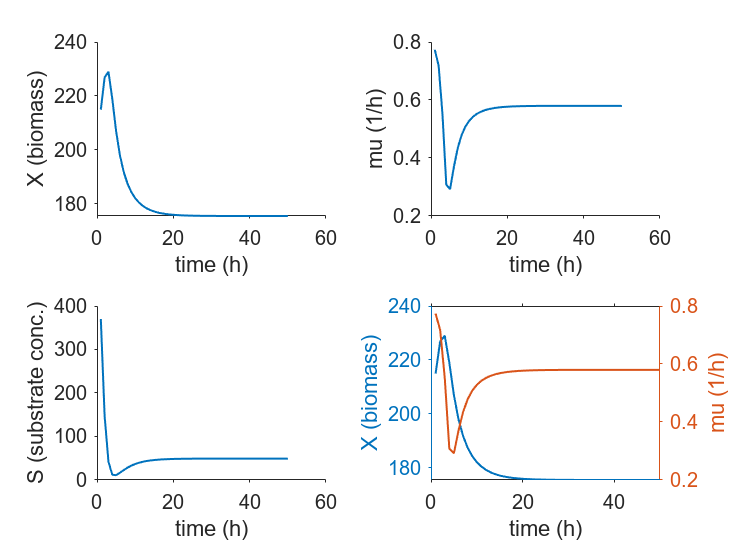


TF = ~isnan(dX_out);
TF(1) = [];
TF(end+1) = false;
figure,
ax1 = nexttile;
plot(1:sum(TF), X_array(TF),'LineWidth',1)
set(ax1,'Tickdir','out','Box','off','FontSize',10);
xlabel(ax1,'time (h)')
ylabel(ax1,'X (biomass)')

ax1 = nexttile;
plot(1:sum(TF), mu_array(TF),'LineWidth',1)
set(ax1,'Tickdir','out','Box','off','FontSize',10);
xlabel(ax1,'time (h)')
ylabel(ax1,'mu (1/h)')

ax1 = nexttile;
plot(1:sum(TF), S_array(TF),'LineWidth',1)
set(ax1,'Tickdir','out','Box','off','FontSize',10);
xlabel(ax1,'time (h)')
ylabel(ax1,'S (substrate conc.)')

ax1 = nexttile;
yyaxis left
plot(1:sum(TF), X_array(TF),'LineWidth',1)
xlabel(ax1,'time (h)')
ylabel(ax1,'X (biomass)')
yyaxis right
plot(1:sum(TF), mu_array(TF),'LineWidth',1)
set(ax1,'Tickdir','out','FontSize',10);
ylabel(ax1,'mu (1/h)')
xlim(ax1,[0,N]*delt_t)